# Block Scheme Reduction Exploiting the Symbolic Math Toolbox

## Systematic Block-Scheme Reduction Procedure -  A Recap

Given a block scheme, as for example

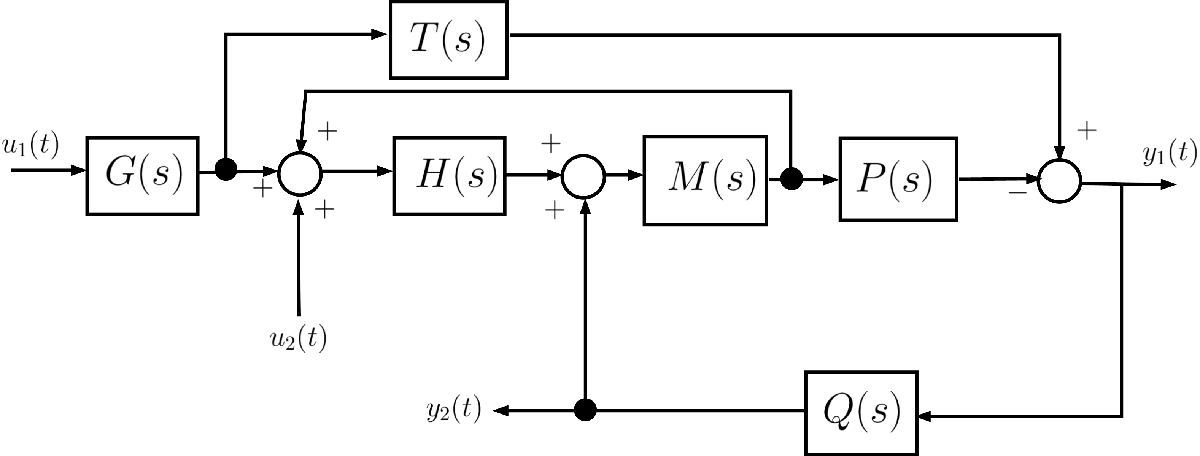

a systematic reduction procedure to determine the overall equivalent transfer function from the selected input to the chosen output could be the following:

- **assign**  an intermediate **variable** to **each oriented arc** in the scheme that is not yet associated with a variable (the input and output arcs already have a corresponding variable);

- **write** the **relationships** (in terms of the **Laplace transform**) between the inputs, the intermediate variables and the outputs. Take into account the topological structure of the scheme (presence of summation or interconnection nodes) and each transfer function acting in the scheme itself;

- **reduce** the **system of linear equations** already obtained by substituting every intermediate variable with a suitable expression using only the input and output variables.

## A First Example

Given the scheme [exercise from the written examination in date 2022/02/04]

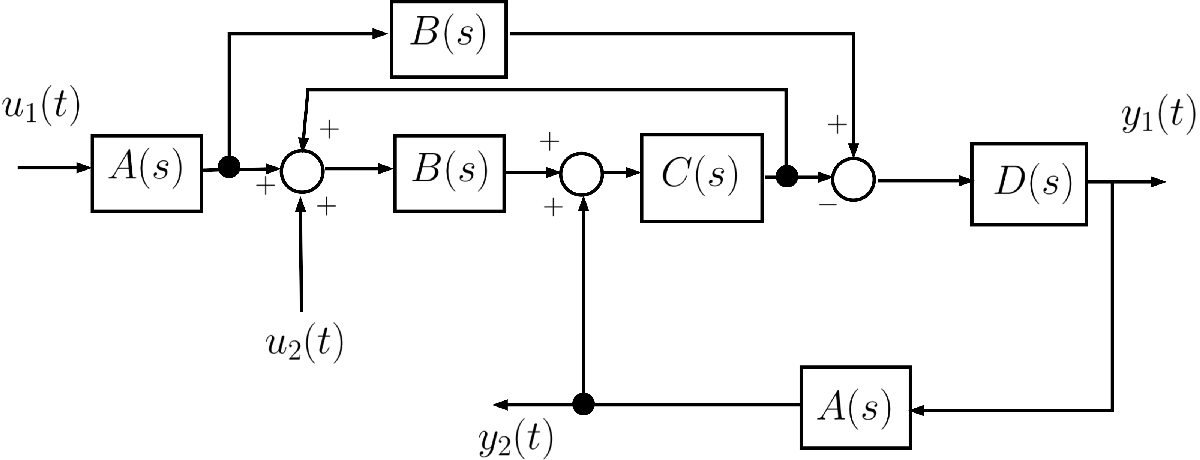

let's compute the overall equivalent transfer function from the input $u_1(t)$ to the output $y_1(t)$.

### Step 1: Associate a Variable to each Arc

This task should be **manually** **fulfilled**. For example, the resulting scheme can appear as the following:

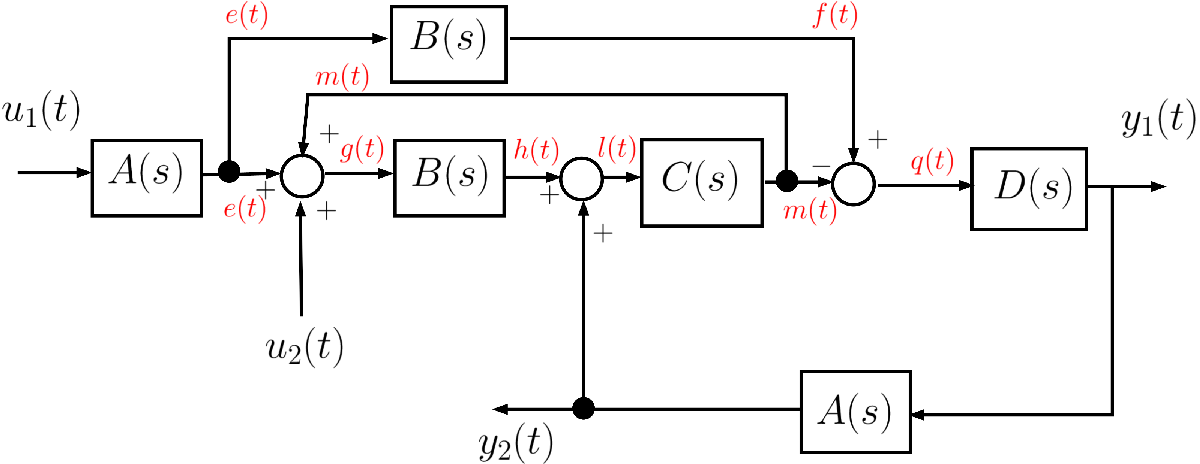

### Step 2: Write the System of Linear Equations describing the Block Scheme

This task should be **manually** **fulfilled**. According to the labelling performed in "Step 1", we obtain the following system of linear equations:


$$\left\{ \begin{array}{rcl}
E &=& A\, U_1 \\
F &=& B\, E \\
G &=& E+M\\
H &=& B\,G\\
L &=& H + Y_2\\
M &=& C\,L\\
Q &=& F-M\\
Y_1 &=& D\,Q\\
Y_2 &=& A\,Y_1
\end{array} \right.$$


where $A, B, C$ and $D$ are the transfer functions and $E, F, G, H, L, M$, and $Q$ are the Laplace transforms of the variables $e(t), f(t)$, etc.

Please** pay attention**: we are considering the scenario when $u_2(t) = 0 \; \forall t$.

### Step 3: Solve the System of Linear Equations

Now we can exploit the *Symbolic Math Toolbox* functions to compute the desired transfer function.

Let's start defining the variables, the transfer function and writing the set of equations, according the result in Step 2.

clear

% -------------------------------------------------------------------
% let's define the Laplace transforms of the variables (using simply
% capital letters)
syms U1 Y1 Y2      % the input and the outputs of the system
syms E F G H L M Q % the intermediate variables
syms A B C D       % the given transfer functions
% -------------------------------------------------------------------

% ---- the equations ----
eqn1 = A*U1 == E;
eqn2 = B*E  == F;
eqn3 = E+M  == G;
eqn4 = B*G  == H;
eqn5 = H+Y2 == L;
eqn6 = C*L  == M;
eqn7 = F-M  == Q;
eqn8 = D*Q  == Y1;
eqn9 = A*Y1 == Y2;
% assembling the set of equations 
eqnS =[eqn1; eqn2; eqn3; eqn4; eqn5; eqn6; eqn7; eqn8; eqn9];
% ---- the equations ----


#### Important Remark

Note: we wrote down nine independent equations in ten variables. So, the resulting system of linear equations is under-determined. According to Rouche-Capelli’s theorem, the system solution will be expressed using one “free” parameter (i.e., one of the ten variables).

Remember: we are looking for the expression of the transfer function from input $U_1$ to output $Y_1$. So, if we were able to split the current set of variables, "extracting" the input $U_1$ from the variables to use it as a "free parameter" in the known terms of the equations, then we would have nine independent equations in nine variables. We could quickly solve the system of equations, obtaining the expression of the transfer function sought.

#### A very useful trick

How to split the set of variables, moving $U_1$ in the vector of known terms of the system of equations?

Easy! Use `equationsToMatrix( )`

help equationsToMatrix

--- help for sym/equationsToMatrix ---

 sym/equationsToMatrix - Convert linear equations to matrix form
    This MATLAB function converts equations eqns to matrix form.

    Syntax
      [A,b] = equationsToMatrix(eqns)
      [A,b] = equationsToMatrix(eqns,vars)
      A = equationsToMatrix(___)

    Input Arguments
      eqns - Linear equations
        vector of symbolic equations or expressions
      vars - Independent variables
        vector of symbolic variables (default) |
        vector of symbolic functions

    Output Arguments
      A - Coefficient matrix
        symbol

% ---- the set of variables -----------------
varS = [E; F; G; H; L; M; Q; Y1; Y2]; % <-- U1 is no more in the set of variables! 
                                      % We "moved" U1 in the vector of
                                      % known terms vectB

% let's write the system of linear equations in matrix form!
[matA, vectB] = equationsToMatrix(eqnS, varS)

$$matA = \left(\begin{array}{ccccccccc} -1 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ B & -1 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 1 & 0 & -1 & 0 & 0 & 1 & 0 & 0 & 0\\ 0 & 0 & B & -1 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 1 & -1 & 0 & 0 & 0 & 1\\ 0 & 0 & 0 & 0 & C & -1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0 & 0 & -1 & -1 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & \text{D} & -1 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & A & -1 \end{array}\right)$$

$$vectB = \left(\begin{array}{c} -A\,U_{1}\\ 0\\ 0\\ 0\\ 0\\ 0\\ 0\\ 0\\ 0 \end{array}\right)$$

Now we can solve the system of linear equations and rearrange the expression of the transfer function from $u_1(t)$ to $y_1(t)$:

% compute the solution in term of the "free parameter" U1
X = simplify(linsolve(matA,vectB))

$$X = \begin{array}{l} \left(\begin{array}{c} A\,U_{1}\\ A\,B\,U_{1}\\ \frac{A\,U_{1}\,\sigma_{2}}{\sigma_{1}}\\ \frac{A\,B\,U_{1}\,\sigma_{2}}{\sigma_{1}}\\ \frac{A\,B\,U_{1}\,\sigma_{4}}{\sigma_{1}}\\ \frac{A\,B\,C\,U_{1}\,\sigma_{4}}{\sigma_{1}}\\ -\frac{A\,B\,U_{1}\,\sigma_{3}}{\sigma_{1}}\\ -\frac{A\,B\,\text{D}\,U_{1}\,\sigma_{3}}{\sigma_{1}}\\ -\frac{A^{2}\,B\,\text{D}\,U_{1}\,\sigma_{3}}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=A\,C\,\text{D}-B\,C+1\\ \sigma_{2}=A\,C\,\text{D}+A\,B\,C\,\text{D}+1\\ \sigma_{3}=C+B\,C-1\\ \sigma_{4}=A\,\text{D}+1 \end{array}$$

% the only solution term we are looking for
Y1SOL = collect(simplify(X(8)), U1)

$$Y1SOL = \left(-\frac{A\,B\,\text{D}\,\left(C+B\,C-1\right)}{A\,C\,\text{D}-B\,C+1}\right)\,U_{1}$$

Finally, the transfer function is

TF_u1_2_y1 = subs(Y1SOL, U1, 1)

$$TF\_u1\_2\_y1 = -\frac{A\,B\,\text{D}\,\left(C+B\,C-1\right)}{A\,C\,\text{D}-B\,C+1}$$

What if we also determine the transfer function from $u_1(t)$ to $y_2(t)$? 

Note: the result is already available:


Y2SOL = collect(simplify(X(9)), U1);
TF_u1_2_y2 = subs(Y2SOL, U1, 1)

$$TF\_u1\_2\_y2 = -\frac{A^{2}\,B\,\text{D}\,\left(C+B\,C-1\right)}{A\,C\,\text{D}-B\,C+1}$$

## A Second Example

Given the scheme [exercise from the written examination in date 2022/02/04]

let's compute the overall equivalent transfer function from the input $u_2(t)$ to the output $y_1(t)$.

### Step 0: Simplify the Scheme

It is advantageous to simplify the scheme before applying the reduction procedure. In fact, for linearity, we assume that the input $u_1(t)$ is null, and consequently, we can eliminate some blocks and nodes from the diagram.

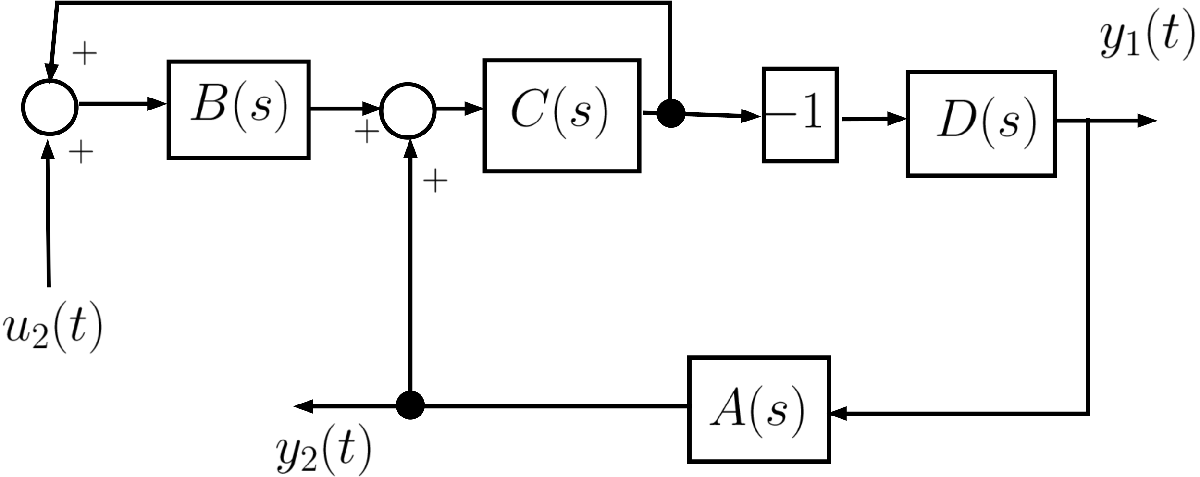

### Step 1: Associate a Variable to each Arc

This task should be **manually** **fulfilled**. For example, the resulting scheme can appear as the following:

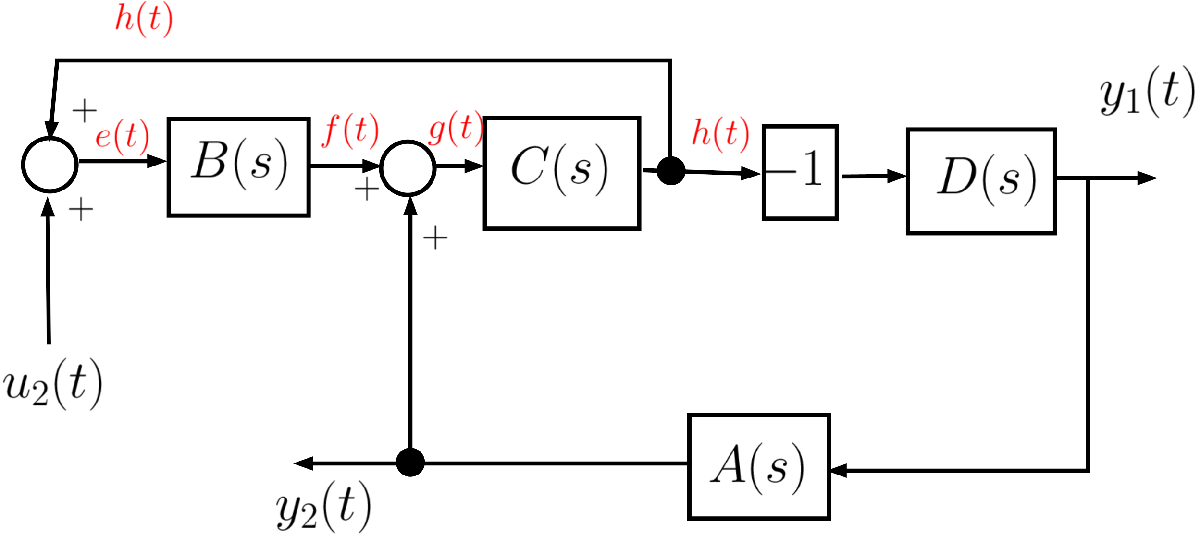

### Step 2: Write the System of Linear Equations describing the Block Scheme

This task should be **manually** **fulfilled**. According to the labelling performed in "Step 1", we obtain the following system of linear equations:


$$\left\{ \begin{array}{rcl}
E &=& H+U_2 \\
F &=& B\, E \\
G &=& F+Y_2\\
H &=& C\,G\\
Y_1 &=& -D\,H\\
Y_2 &=& A\,Y_1
\end{array} \right.$$


where $A, B, C$ and $D$ are the transfer functions and $E, F, G$, and $H$ are the Laplace transforms of the variables $e(t), f(t)$, etc.

Please** pay attention**: we are considering the scenario when $u_1(t) = 0 \; \forall t$.

### Step 3: Solve the System of Linear Equations

Now we can exploit the *Symbolic Math Toolbox* functions to compute the desired transfer function.

Let's start defining the variables, the transfer function and writing the set of equations, according the result in Step 2.

clear

% -------------------------------------------------------------------
% let's define the Laplace transforms of the variables (using simply
% capital letters)
syms U2 Y1 Y2 % the input and the outputs of the system
syms E F G H  % the intermediate variables
syms A B C D  % the given transfer functions
% -------------------------------------------------------------------

% ---- the equations ----
eqn1 = H+U2 == E;
eqn2 = B*E  == F;
eqn3 = F+Y2  == G;
eqn4 = C*G  == H;
eqn5 = -D*H  == Y1;
eqn6 = A*Y1 == Y2;
% assembling the set of equations 
eqnS =[eqn1; eqn2; eqn3; eqn4; eqn5; eqn6];
% ---- the equations ----


#### Important Remark

Note: we wrote down six independent equations in seven variables. So, the resulting system of linear equations is under-determined. According to Rouche-Capelli’s theorem, the system solution will be expressed using one “free” parameter (i.e., one of the ten variables).

Remember: we are looking for the expression of the transfer function from input $U_2$ to output $Y_2$. So, if we were able to split the current set of variables, "extracting" the input $U_2$ from the variables to use it as a "free parameter" in the known terms of the equations, then we would have nine independent equations in nine variables. We could quickly solve the system of equations, obtaining the expression of the transfer function sought.

#### A very useful trick

How to split the set of variables, moving $U_2$ in the vector of known terms of the system of equations?

Easy! Use `equationsToMatrix( )`

% ---- the set of variables -----------------
varS = [E; F; G; H; Y1; Y2]; % <-- U1 is no more in the set of variables! 
                                      % We "moved" U1 in the vector of
                                      % known terms vectB

% let's write the system of linear equations in matrix form!
[matA, vectB] = equationsToMatrix(eqnS, varS)

$$matA = \left(\begin{array}{cccccc} -1 & 0 & 0 & 1 & 0 & 0\\ B & -1 & 0 & 0 & 0 & 0\\ 0 & 1 & -1 & 0 & 0 & 1\\ 0 & 0 & C & -1 & 0 & 0\\ 0 & 0 & 0 & -\text{D} & -1 & 0\\ 0 & 0 & 0 & 0 & A & -1 \end{array}\right)$$

$$vectB = \left(\begin{array}{c} -U_{2}\\ 0\\ 0\\ 0\\ 0\\ 0 \end{array}\right)$$

Now we can solve the system of linear equations and rearrange the expression of the transfer function from $u_1(t)$ to $y_1(t)$:

% compute the solution in term of the "free parameter" U1
X = simplify(linsolve(matA,vectB))

$$X = \begin{array}{l} \left(\begin{array}{c} \frac{U_{2}\,\left(A\,C\,\text{D}+1\right)}{\sigma_{1}}\\ \frac{B\,U_{2}\,\left(A\,C\,\text{D}+1\right)}{\sigma_{1}}\\ \frac{B\,U_{2}}{\sigma_{1}}\\ \frac{B\,C\,U_{2}}{\sigma_{1}}\\ -\frac{B\,C\,\text{D}\,U_{2}}{\sigma_{1}}\\ -\frac{A\,B\,C\,\text{D}\,U_{2}}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=A\,C\,\text{D}-B\,C+1 \end{array}$$

% the only solution term we are looking for
Y1SOL = collect(simplify(X(5)), U2)

$$Y1SOL = \left(-\frac{B\,C\,\text{D}}{A\,C\,\text{D}-B\,C+1}\right)\,U_{2}$$

Finally, the transfer function is

TF_u2_2_y1 = subs(Y1SOL, U2, 1)

$$TF\_u2\_2\_y1 = -\frac{B\,C\,\text{D}}{A\,C\,\text{D}-B\,C+1}$$

What if we also determine the transfer function from $u_2(t)$ to $y_2(t)$? 

Note: the result is already available:


Y2SOL = collect(simplify(X(6)), U2);
TF_u2_2_y2 = subs(Y2SOL, U2, 1)

$$TF\_u2\_2\_y2 = -\frac{A\,B\,C\,\text{D}}{A\,C\,\text{D}-B\,C+1}$$